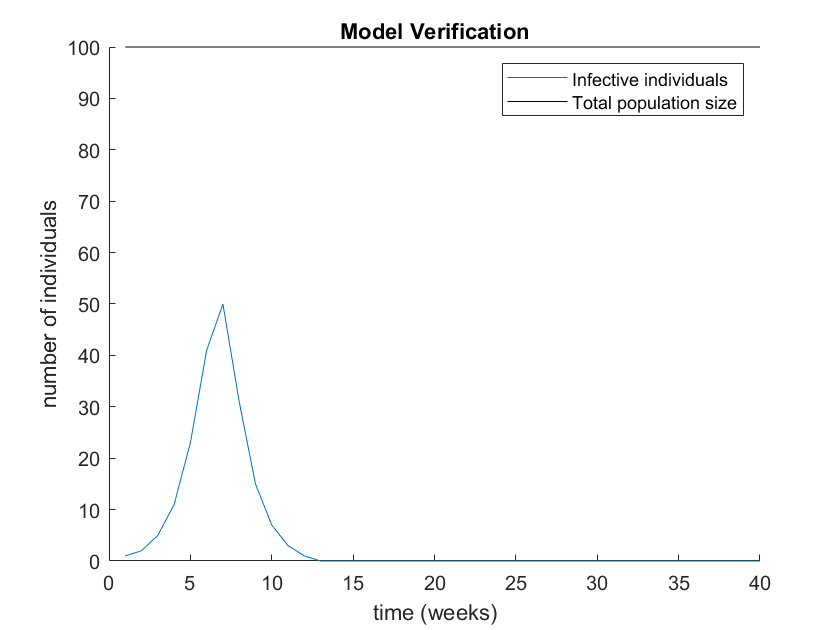

beta = 1/50; % Infection Rate
gamma = 1/2; % Recovery rate in 1/weeks
population = 100;
i1_0 = 1; % Number of initial infections
s1_0 = population - i1_0;
r1_0 = 0; 
%masks = 1/5;
num_steps = 40; % Number of weeks Simulated
figure(1); clf; hold on
    [S,I,R,W]=sir_v1_simulate(s1_0, i1_0, r1_0, beta, gamma, num_steps);
    plot(W,I);
    total = I + R + S;
    plot (W, total, 'k-')
    xlabel ("time (weeks)")
    ylabel ("number of individuals")
    legend(["Infected individuals","Total population size"]);
    title("Model Verification")
hold off